# **WSN simulation and Calculating Network's Lifetime **

###     Wireless Sensor Networks (WSNs) are crucial for applications like environmental monitoring and smart cities, where energy efficiency and network lifetime are vital. This project simulates a WSN with 100 randomly deployed sensor nodes, each initialized with 2 Joules of energy.To enable efficient communication, approximately 5 nodes are elected as cluster heads per cycle. These cluster heads aggregate data from neighboring nodes and transmit it to the sink, playing a key role in energy management.

###     An alternative setup with fixed cluster heads, uniformly distributed along a circle centered on the sink, is also studied to assess its impact on energy consumption and performance. Key metrics analyzed include remaining energy, active nodes over time, and network lifetime, providing insights into optimizing WSN configurations for better efficiency and lifespan.

-  **Clearing the working space, Close whole figures, before starting :**

close all;
clear;
clc;

- **Defining the Parameters that will be used across the scope of the project :**

% Parameters
N = 100;                                                    % Number of sensor nodes
A = 100;                                                    % Network area size (100m x 100m)
x = randi([0, A], 1, N);                                    % X-coordinates of sensor nodes
y = randi([0, A], 1, N);                                    % Y-coordinates of sensor nodes
E_initial = 2;                                              % Initial energy for each node (2 Joules)
sink = [A/2, A/2];                                          % Sink located at the center
Eelec = 50e-9;                                              % Energy for running transmitter/receiver circuitry (J/bit)
Eagg = 50e-9;                                               % Energy for aggregation (J/bit/signal)
epsilon_fs = 10e-9;                                         % Free-space energy parameter (J/bit/m^2)
epsilon_mp = 0.0013e-9;                                     % Multi-path energy parameter (J/bit/m^4)
d0 = sqrt(epsilon_fs / epsilon_mp);                         % Threshold distance
k = 4000;                                                   % Number of bits transmitted per cycle
C = 5;                                                      % Number of cycles before new CH election
percentage_CH = 0.05;                                       % 5% of nodes elected as CHs


% Initialize node states
E = E_initial * ones(1, N);                                 % Energy for all nodes
node_dead = false(1, N);                                    % Node death status
alive_nodes = N;                                            % Number of alive nodes
alive_nodes_per_cycle = [];                                 % Store number of active nodes per cycle
remaining_energy_per_cycle = [];                            % Store remaining energy per cycle
dead_nodes_T1 = [];                                         % Dead nodes at first death
cycles = 0;                                                 % Cycle count


  **Part A **** The network topology with 100 sensors randomly deployed , with the sink at the center :**

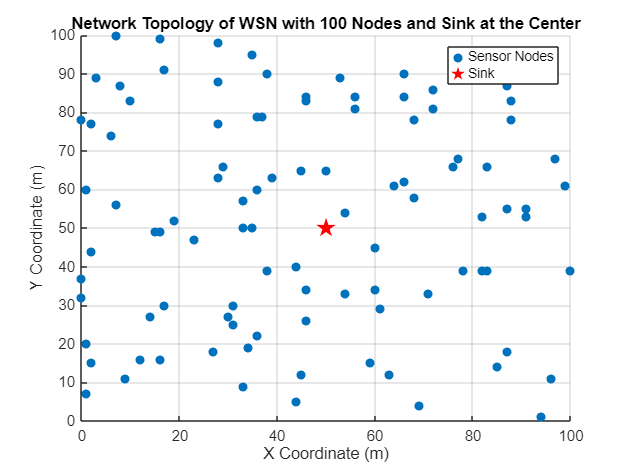

figure(1);
scatter(x, y, 'filled');                                                % Plot sensor nodes
hold on;
plot(sink(1), sink(2), 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); % Plot sink
title('Network Topology of WSN with 100 Nodes and Sink at the Center');
xlabel('X Coordinate (m)');
ylabel('Y Coordinate (m)');
legend('Sensor Nodes', 'Sink');
grid on;

                                                                   ** Fig [1]**

                              **The figure show the WSN with 100 sensors  , that are randomaly**

**                               deployed and the Sink at the Center of the Network at (50,50). **                   

- **Cluster head election in some part of the project is based on the energy levels of the still-alive nodes. First, the energies of all active nodes are sorted in descending order. From this sorted list, the top five nodes with the highest energy levels are selected and designated as cluster heads. The remaining nodes are classified as non-cluster heads, and they transmit their data to the nearest cluster head for further processing. This approach ensures that the most energy-efficient nodes take on the energy-intensive role of cluster heads, thereby optimizing the overall energy utilization and extending the network's lifetime.**

% Cluster Head Election Function
function [CH_indices, non_CH_indices] = elect_cluster_heads(alive_indices, E, percentage)
    % Sort alive nodes by their energy in descending order
    [~, sorted_indices] = sort(E(alive_indices), 'descend');
    sorted_alive_indices = alive_indices(sorted_indices);
    % Select the top nodes with the highest energy as CHs
    num_CH = round(length(alive_indices) * percentage);
    CH_indices = sorted_alive_indices(1:num_CH);
    % Remaining nodes are non-CHs
    non_CH_indices = setdiff(alive_indices, CH_indices);
end

% Find Nearest Cluster Head Function
function nearest_CH = find_nearest_CH(node_idx, CH_indices, x, y)
    distances = sqrt((x(node_idx) - x(CH_indices)).^2 + (y(node_idx) - y(CH_indices)).^2);
    [~, min_idx] = min(distances);
    nearest_CH = CH_indices(min_idx);
end

- **This part involves simulating the WSN by electing cluster heads, which are responsible for transmitting aggregated data from the sensor nodes to the sink. The transmission is carried out using either free-space propagation or multi-fading propagation models, depending on the communication scenario : **

% Simulation Loop
while alive_nodes > 0
    % Get alive nodes
    alive_indices = find(~node_dead);                      
    % Elect new CHs every C cycles
    if mod(cycles, C) == 0                                
        [CH_indices, non_CH_indices] = elect_cluster_heads(alive_indices, E, percentage_CH);
    end
    % Starting Simulation for the network 
    for i = alive_indices
        % Find the nearest CH
        nearest_CH = find_nearest_CH(i, CH_indices, x, y);
        d_to_CH = sqrt((x(i) - x(nearest_CH)).^2 + (y(i) - y(nearest_CH)).^2);
        d_CH_to_sink = sqrt((x(nearest_CH) - sink(1)).^2 + (y(nearest_CH) - sink(2)).^2);
        % Calculate energy consumption for transmission to CH
        if d_to_CH <= d0
            energy_tx = k * Eelec + k * epsilon_fs * d_to_CH.^2;  % Element-wise power
        else
            energy_tx = k * Eelec + k * epsilon_mp * d_to_CH.^4;  % Element-wise power
        end

        % Deduct energy for data transmission
        if E(i) > energy_tx
            E(i) = E(i) - energy_tx;
        else
            % Node dies
            node_dead(i) = true;  
            alive_nodes = alive_nodes - 1;
            if isempty(dead_nodes_T1) && alive_nodes == N-1
                % Capture first dead nodes
                dead_nodes_T1 = find(node_dead); 
            end
            % Skip further processing for this node
            continue; 
        end

        % Cluster Head Energy Consumption
        if ismember(i, CH_indices)
            % Aggregation and transmission to sink
            if d_CH_to_sink <= d0
                energy_CH = k * Eelec + k * epsilon_fs * d_CH_to_sink.^2 + k * Eagg;  % Element-wise power
            else
                energy_CH = k * Eelec + k * epsilon_mp * d_CH_to_sink.^4 + k * Eagg;  % Element-wise power
            end
            % Deduct energy for data transmission
            if E(i) > energy_CH
                E(i) = E(i) - energy_CH;
            else
                % CH dies
                node_dead(i) = true; 
                alive_nodes= alive_nodes - 1;
                if isempty(dead_nodes_T1) && alive_nodes == N-1
                    % Capture first dead nodes
                    dead_nodes_T1 = find(node_dead); 
                end
            end
        end
    end

    % Store results for this cycle
    alive_nodes_per_cycle = [alive_nodes_per_cycle, alive_nodes];
    % Store remaining energy
    remaining_energy_per_cycle = [remaining_energy_per_cycle; E]; 
    % Increment cycle count
    cycles = cycles + 1; 
end

- **Part B**** Number of Active Nodes versus Number of Cycles till the death of last Node, for every C cycles =5 : **

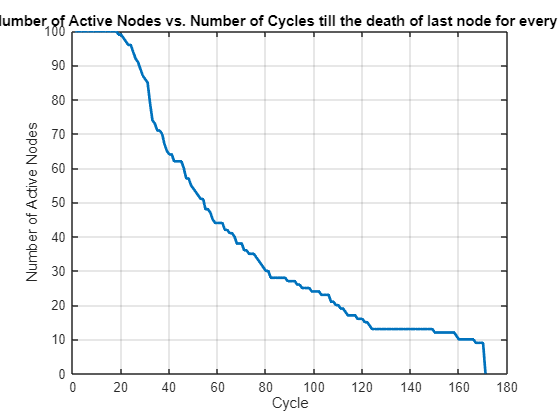

figure(2);
plot(1:cycles, alive_nodes_per_cycle, 'LineWidth', 2);
title('Number of Active Nodes vs. Number of Cycles till the death of last node for every C=5');
xlabel('Cycle');
ylabel('Number of Active Nodes');
grid on;% Plot active nodes vs. cycles with indication for T1 (First Node Death)

**                                                                Fig[2]**

**                         The plot show the number of active Nodes , versus number of Cycles**

**                               till the death of last Nodes , for every C=5 ,  it appears**

**                                   that it starts from 100 sensors and starts to decay**

**                                                              till reaching zero . **

- **Part C_****1  Number of Active Nodes versus Number of Cycles till the death of last Node, for every C cycles =5 , with indication for T1 , which indicates first node death  : **

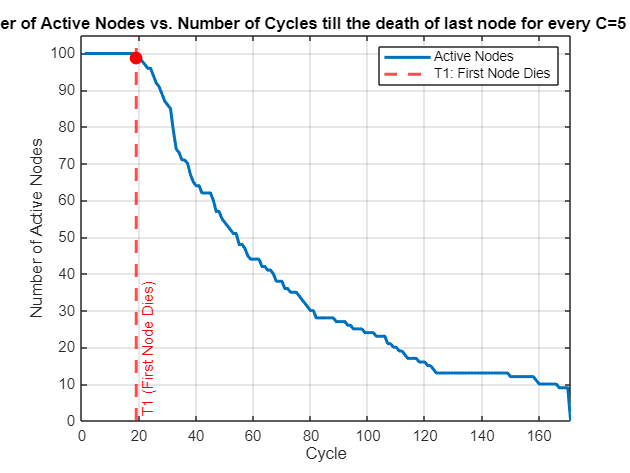

figure(3);
plot(1:cycles, alive_nodes_per_cycle, 'LineWidth', 2);
title('Number of Active Nodes vs. Number of Cycles till the death of last node for every C=5 (with T1)');
xlabel('Cycle');
ylabel('Number of Active Nodes');
grid on;
% Mark T1 (First Node Death) on the plot
T1 = find(alive_nodes_per_cycle == N-1, 1);       % Find cycle where first node dies
% Plot vertical lines to mark T1
hold on;
xline(T1, 'r--', 'LineWidth', 2, 'Label', 'T1 (First Node Dies)', 'LabelVerticalAlignment', 'bottom');
% Annotations for T1
plot(T1, alive_nodes_per_cycle(T1), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
% Adjust axis limits for wider scale
xlim([0 max(T1*1.2, length(alive_nodes_per_cycle))]); % Expands the x-axis by 20% more than T1
ylim([0 N+5]); % Adds a small buffer to the y-axis to give more space for labels
% Add labels and grid
legend('Active Nodes', 'T1: First Node Dies');
hold off;

**                                                                Fig[3]**

**                         The plot show the number of active Nodes , versus number of Cycles**

**                                with indication for T1,  till the death of last Nodes , for every C=5 , **

**                                        it appears that it starts from 100 sensors and starts to decay**

**                                                              till reaching zero . **

- **Part C_2**** The remaining energy at the WSN after T1** : 

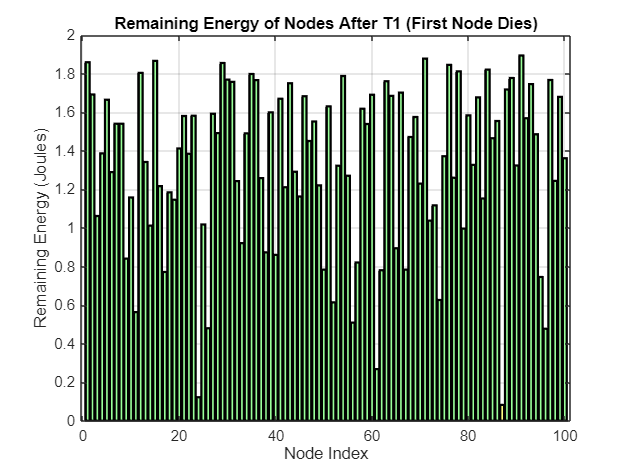

% Plot remaining energy after T1
figure(3);
% Create a bar plot for the remaining energy at T1
bar_handles = bar(remaining_energy_per_cycle(T1, :)); 
title('Remaining Energy of Nodes After T1 (First Node Dies)');
xlabel('Node Index');
ylabel('Remaining Energy (Joules)');
grid on;

% Set the colormap for alive (faded green) and dead (vibrant orange) nodes
faded_alive_color = [0.6, 1, 0.6]; % Light pastel green for alive nodes
bright_dead_color = [1, 1, 0.5];   % Vibrant orange for dead nodes

% Highlight nodes by changing their colors
hold on;
for i = 1:length(bar_handles.YData)
    if ismember(i, dead_nodes_T1)
        % Set color for dead nodes (vibrant orange)
        bar(i, remaining_energy_per_cycle(T1, i), 'FaceColor', bright_dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        % Set color for alive nodes (faded green)
        bar(i, remaining_energy_per_cycle(T1, i), 'FaceColor', faded_alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off;

**                                                                Fig[4]**

**                    The plot shows the remaining energy at the network , after T1 the death of FIrst Node**

**                             , the range of energies is among [0,2] , and the green items indicates the alive Nodes **

**                                         , and Orange items indicates the death ones , and it appears there's**

**                                                    just one node dead in the orange colour . **

- **Part C_3**** The Cycle at which first node dead happen , and the index of first node dead at T1 : **

% Display Results
disp(['Index of Dead nodes at T1: ', num2str(dead_nodes_T1)]);

Index of Dead nodes at T1: 87


disp(['Cycle at which first node dead  ', num2str(T1)] )

Cycle at which first node dead  19


disp(['Number of dead nodes at T1: ', num2str(length(dead_nodes_T1))]);

Number of dead nodes at T1: 1


- **This part explores the variation of cycles C, which determine how often cluster heads are elected. The network is simulated to analyze how different values of C impact the network's lifetime and the remaining energy at the optimum C : **

% Initialize variables to store T1 and T2 values
C_values = 1:10;                                            % Test C values from 1 to 10
T1_values = zeros(length(C_values), 1);
% Loop over different values of C
for c_idx = 1:length(C_values)
    % Current C value
    C = C_values(c_idx);
    % Initialize node states for each C
    E_C = E_initial * ones(1, N);                             % Energy for all nodes
    node_dead_C = false(1, N);                                % Node death status
    alive_nodes_C = N;                                        % Number of alive nodes
    dead_nodes_T1_C = [];                                     % Dead nodes at first death
    cycles_C = 0;                                             % Cycle count
    T1_C = 0;                                                 % First dead node cycle
    alive_nodes_per_cycle_C=[];                               % remaining alive nodes per cycle 
    remaining_energy_per_cycle_C=[];                          % remaining energy per cycle 
    % Simulation Loop for current C
while alive_nodes_C > 0
    % Get alive nodes
    alive_indices = find(~node_dead_C);                      
    % Elect new CHs every C cycles
    if mod(cycles_C, C) == 0                                
        [CH_indices, non_CH_indices] = elect_cluster_heads(alive_indices, E_C, percentage_CH);
    end
    % Starting Simulation for the network 
    for i = alive_indices
        % Find the nearest CH
        nearest_CH = find_nearest_CH(i, CH_indices, x, y);
        d_to_CH = sqrt((x(i) - x(nearest_CH)).^2 + (y(i) - y(nearest_CH)).^2);
        d_CH_to_sink = sqrt((x(nearest_CH) - sink(1)).^2 + (y(nearest_CH) - sink(2)).^2);
        % Calculate energy consumption for transmission to CH
        if d_to_CH <= d0
            energy_tx = k * Eelec + k * epsilon_fs * d_to_CH.^2;  % Element-wise power
        else
            energy_tx = k * Eelec + k * epsilon_mp * d_to_CH.^4;  % Element-wise power
        end
        % Deduct energy for data transmission
        if E_C(i) > energy_tx
            E_C(i) = E_C(i) - energy_tx;
        else
            % Node dies
            node_dead_C(i) = true;  
            alive_nodes_C = alive_nodes_C - 1;
            if isempty(dead_nodes_T1_C) && alive_nodes_C == N - 1
                % Capture first dead nodes
                dead_nodes_T1_C = find(node_dead_C); 
                T1_C = cycles_C; % Record T1
            end
            % Skip further processing for this node
            continue; 
        end
        % Cluster Head Energy Consumption
        if ismember(i, CH_indices)
            % Aggregation and transmission to sink
            if d_CH_to_sink <= d0
                energy_CH = k * Eelec + k * epsilon_fs * d_CH_to_sink.^2 + k * Eagg;  % Element-wise power
            else
                energy_CH = k * Eelec + k * epsilon_mp * d_CH_to_sink.^4 + k * Eagg;  % Element-wise power
            end
            % Deduct energy for data transmission
            if E_C(i) > energy_CH
                E_C(i) = E_C(i) - energy_CH;
            else
                % CH dies
                node_dead_C(i) = true; 
                alive_nodes_C = alive_nodes_C - 1;
                if isempty(dead_nodes_T1_C) && alive_nodes_C == N - 1
                    % Capture first dead nodes
                    dead_nodes_T1_C = find(node_dead_C); 
                    T1_C = cycles_C; % Record T1
                end
            end
        end
    end

    % Store results for this cycle
    alive_nodes_per_cycle_C = [alive_nodes_per_cycle_C, alive_nodes_C];
    remaining_energy_per_cycle_C = [remaining_energy_per_cycle_C; E_C]; 
    cycles_C = cycles_C + 1; 
end
% Store T1 for this C
T1_values(c_idx) = T1_C;
end 

- **Part D_1**** The network Life Time T1 which indicates the first Node death VS the number of cycles that are taken each time : **

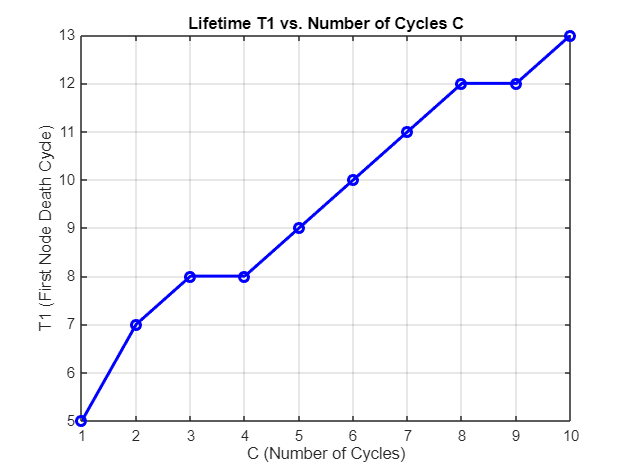

% Plot lifetime T1 versus C
figure(4);
plot(C_values, T1_values, 'b-o', 'LineWidth', 2);
title('Lifetime T1 vs. Number of Cycles C');
xlabel('C (Number of Cycles)');
ylabel('T1 (First Node Death Cycle)');
grid on;

**                                                               Fig[5]**

**                            The figure shows T1 which indicates the first node death VS Number of Cycles C , **

**                                         and it appears that T1 increases when C increase ,**

**                                            which are the Cyles that  are used to elect the CHs . **

- **Part D_2**** The Optimum Number of Cycles [C] that  maximize Network lifeTimes [T1] :** 

% Find the optimum C
[optimum_T1, opt_idx] = max(T1_values);
optimum_C = C_values(opt_idx);
disp(['optimum_C: ', num2str(optimum_C)]);
disp(['optimum_T1: ', num2str(optimum_T1)]);

optimum_C: 10


optimum_T1: 13


- **Simulating the WSN over the Optimum C , to find the remaining energy at the network  , after T1 in case of Optimum C : **

% Initialization for Remaining Energy after T1 for Optimum C
E_Optimum = E_initial * ones(1, N);                            % Reinitialize energy for all nodes
node_dead_Optimum = false(1, N);                               % Node death status
alive_nodes_Optimum = N;                                       % Number of alive nodes
dead_nodes_T1_Optimum=[];                                      % Dead Nodes at first Death oin case of optimum C
alive_nodes_per_cycle_Optimum =[];                             % alive nodes per cycle in case of optimum C 
remaining_energy_per_cycle_Optimum = [];                       % Energy record for each cycle
cycles_Optimum= 0;                                             % Cycle count
% Simulation Loop
while alive_nodes_Optimum > 0
    % Get alive nodes
    alive_indices = find(~node_dead_Optimum);                      
    % Elect new CHs every optimum_C cycles
    if mod(cycles_Optimum, optimum_C) == 0                                 
        [CH_indices, non_CH_indices] = elect_cluster_heads(alive_indices, E_Optimum, percentage_CH);
    end
    % Starting Simulation for the network 
    for i = alive_indices
        % Find the nearest CH
        nearest_CH = find_nearest_CH(i, CH_indices, x, y);
        d_to_CH = sqrt((x(i) - x(nearest_CH)).^2 + (y(i) - y(nearest_CH)).^2);
        d_CH_to_sink = sqrt((x(nearest_CH) - sink(1)).^2 + (y(nearest_CH) - sink(2)).^2);
        % Calculate energy consumption for transmission to CH
        if d_to_CH <= d0
            energy_tx = k * Eelec + k * epsilon_fs * d_to_CH.^2;  % Element-wise power
        else
            energy_tx = k * Eelec + k * epsilon_mp * d_to_CH.^4;  % Element-wise power
        end
        % Deduct energy for data transmission
        if E_Optimum(i) > energy_tx
            E_Optimum(i) = E_Optimum(i) - energy_tx;
        else
            % Node dies
            node_dead_Optimum(i) = true;  
            alive_nodes_Optimum = alive_nodes_Optimum - 1;
            if isempty(dead_nodes_T1_Optimum) && alive_nodes_Optimum == N - 1
                % Capture first dead nodes
                dead_nodes_T1_Optimum = find(node_dead_Optimum); 
            end
            % Skip further processing for this node
            continue; 
        end
        % Cluster Head Energy Consumption
        if ismember(i, CH_indices)
            % Aggregation and transmission to sink
            if d_CH_to_sink <= d0
                energy_CH = k * Eelec + k * epsilon_fs * d_CH_to_sink.^2 + k * Eagg;  % Element-wise power
            else
                energy_CH = k * Eelec + k * epsilon_mp * d_CH_to_sink.^4 + k * Eagg;  % Element-wise power
            end
            % Deduct energy for data transmission
            if E_Optimum(i) > energy_CH
                E_Optimum(i) = E_Optimum(i) - energy_CH;
            else
                % CH dies
                node_dead_Optimum(i) = true; 
                alive_nodes_Optimum = alive_nodes_Optimum - 1;
                if isempty(dead_nodes_T1_Optimum) && alive_nodes_Optimum == N - 1
                    % Capture first dead nodes
                    dead_nodes_T1_Optimum = find(node_dead_Optimum); 
                end
            end
        end
    end
    % Store results for this cycle
    alive_nodes_per_cycle_Optimum = [alive_nodes_per_cycle_Optimum, alive_nodes_Optimum];
    % Store remaining energy
    remaining_energy_per_cycle_Optimum = [remaining_energy_per_cycle_Optimum; E_Optimum]; 
    % Increment cycle count
    cycles_Optimum = cycles_Optimum + 1; 
end

- **Part D_3**** The remaining energy at the network after T1 , in case of optimum Number of Cycles : **

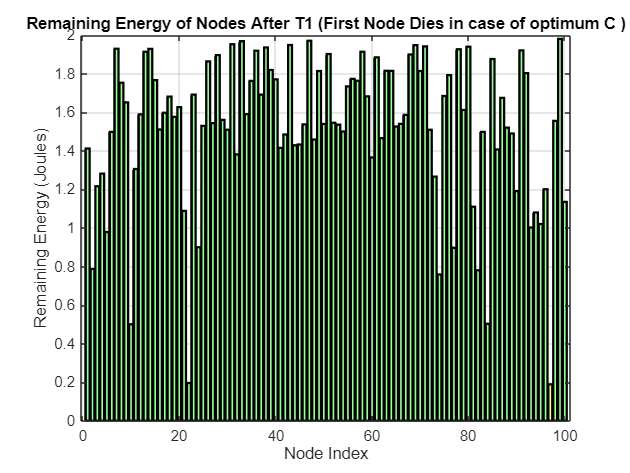

% Find T1_optimum: cycle where the first node dies
T1_optimum = find(alive_nodes_per_cycle_Optimum == N - 1, 1);
% Plot the Remaining Energy after T1 for Optimum C
figure(3);
bar_handles = bar(remaining_energy_per_cycle_Optimum(T1_optimum, :)); 
title('Remaining Energy of Nodes After T1 (First Node Dies in case of optimum C )');
xlabel('Node Index');
ylabel('Remaining Energy (Joules)');
grid on;
% Set colors for alive (faded green) and dead (vibrant orange) nodes
faded_alive_color = [0.6, 1, 0.6]; % Light pastel green for alive nodes
bright_dead_color = [1, 1, 0.5];   % Vibrant orange for dead nodes
% Highlight nodes by changing their colors

hold on;
for i = 1:length(bar_handles.YData)
    if ismember(i, dead_nodes_T1_Optimum)
        % Set color for dead nodes (vibrant orange)
        bar(i, remaining_energy_per_cycle_Optimum(T1_optimum, i), 'FaceColor', bright_dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        % Set color for alive nodes (faded green)
        bar(i, remaining_energy_per_cycle_Optimum(T1_optimum, i), 'FaceColor', faded_alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off ; 

                                                                  **  Fig [6]**

                          **  The figure shows the remaining energy at the WSN network after T1 ,**

**                                    in case of Optimum C , in which the range of energies is among [0,2] **

**                                       , and there's just one node dead in the orange color and **

**                                                the green items indicates the alive ndoes , and the**

**                                                  orange nodes indicates the dead nodes . **

- **This part involves simulating the WSN using an alternative approach for cluster head (CH) selection. Instead of dynamically electing cluster heads, they are uniformly distributed along a circular path centered around the sink. These predefined cluster heads are assigned higher energy levels compared to the other sensor nodes, ensuring they can handle the additional workload effectively. This approach aims to evaluate the impact of fixed cluster head placement on network performance, energy consumption, and overall lifetime : **

% part E 
clc; clear; close all;
% Parameters
N = 100;                                                    % Number of sensor nodes
A = 100;                                                    % Network area size (100m x 100m)
x = randi([0, A], 1, N);                                    % X-coordinates of sensor nodes
y = randi([0, A], 1, N);                                    % Y-coordinates of sensor nodes
E_initial = 2;                                              % Initial energy for sensor nodes (2 Joules)
E_special = 4;                                              % Initial energy for special nodes (4 Joules)
sink = [A/2, A/2];                                          % Sink located at the center
R = 25;                                                     % Radius of circle for special nodes
Eelec = 50e-9;                                              % Energy for transmitter/receiver circuitry (J/bit)
Eagg = 50e-9;                                               % Energy for aggregation (J/bit/signal)
epsilon_fs = 10e-9;                                         % Free-space energy parameter (J/bit/m^2)
epsilon_mp = 0.0013e-9;                                     % Multi-path energy parameter (J/bit/m^4)
d0 = sqrt(epsilon_fs / epsilon_mp);                         % Threshold distance
k = 4000;                                                   % Number of bits transmitted per cycle

% Special nodes placement
theta = linspace(0, 2*pi, 6);                               % Angles for five special nodes
theta(end) = [];                                            % Remove duplicate angle
special_x = sink(1) + R * cos(theta);                       % X-coordinates of special nodes
special_y = sink(2) + R * sin(theta);                       % Y-coordinates of special nodes

% Initialize node states
E = E_initial * ones(1, N);                                 % Energy for sensor nodes
E_special_nodes = E_special * ones(1, 5);                   % Energy for special nodes
remaining_energy_per_cycle=[];
node_dead = false(1, N);                                    % Sensor node death status
special_node_dead = false(1, 5);                            % Special node death status
alive_nodes = N;                                            % Number of alive sensor nodes
alive_special_nodes = 5;                                    % Number of alive special nodes
alive_nodes_per_cycle = [];                                 % Store number of active sensor nodes per cycle
cycles = 0;                                                 % Cycle count
T1_sensor = [];                                             % Cycle of first sensor node death
T1_special = [];                                            % Cycle of first special node death
dead_nodes_T1_S_N=[]; 
dead_nodes_T1_S=[];

- **Part E_A****  Network with 100 Sensors , that are Randomly deployed with sink in the center ,  and the CHS are uniformaly distributed over a Cirle centred at the sink : **

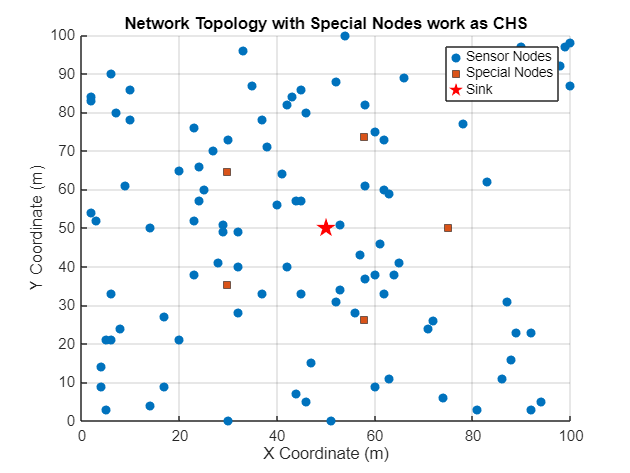

% Plot initial network topology
figure(1);
scatter(x, y, 'filled');                                    % Plot sensor nodes
hold on;
scatter(special_x, special_y, 's', 'filled', 'MarkerEdgeColor', 'k'); % Plot special nodes
plot(sink(1), sink(2), 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); % Plot sink
title('Network Topology with Special Nodes work as CHS');
xlabel('X Coordinate (m)');
ylabel('Y Coordinate (m)');
legend('Sensor Nodes', 'Special Nodes', 'Sink');
grid on;

                                                    **       Fig [7]**

**                            The Figure shows the WSN with 100 sensor Nodes randomly**

**                                deployed with Sink at the Center , CHS are unifomraly**

**                                       distributed over a Circle centered at the Sink . **

- **This part simulates the WSN with 100 sensor nodes randomly deployed across the network. Each sensor node identifies the nearest suitable special node to transmit data to the sink. If the chosen special node is found to be dead, the sensor node will search for another available special node to transmit through. If all special nodes are dead, the sensor node will transmit data directly to the sink. The transmission is modeled using either free-space propagation or multi-path propagation, depending on the communication scenario. This approach ensures efficient data routing and adapts to changes in the network's node status : **

% Simulation Loop
while alive_nodes > 0
    for i = find(~node_dead)
        % Distance to special nodes
        distances_to_special = sqrt((x(i) - special_x).^2 + (y(i) - special_y).^2);
        [min_dist, nearest_special_idx] = min(distances_to_special);
        % Check if all special nodes are dead
        if all(special_node_dead)
            min_dist = sqrt((x(i) - sink(1)).^2 + (y(i) - sink(2)).^2); % Direct to sink
        elseif special_node_dead(nearest_special_idx)
            distances_to_special(special_node_dead) = Inf; % Ignore dead special nodes
            [min_dist, nearest_special_idx] = min(distances_to_special);
        end
        % Energy consumption for transmission
        if min_dist <= d0
            energy_tx = k * Eelec + k * epsilon_fs * min_dist^2;
        else
            energy_tx = k * Eelec + k * epsilon_mp * min_dist^4;
        end
        
        % Update sensor node energy
        if E(i) > energy_tx
            E(i) = E(i) - energy_tx;
        else
            node_dead(i) = true;
            alive_nodes = alive_nodes - 1;
            if isempty(T1_sensor) &&  alive_nodes ==N-1
                % Capture first dead nodes
                dead_nodes_T1_S_N = find(node_dead);
                T1_sensor = cycles + 1;
            end
            continue;
        end
        
        % Special node energy consumption
        if ~all(special_node_dead) && ~special_node_dead(nearest_special_idx)
            d_special_to_sink = sqrt((special_x(nearest_special_idx) - sink(1))^2 + (special_y(nearest_special_idx) - sink(2))^2);
            if d_special_to_sink <= d0
                energy_special_tx = k * Eelec + k * epsilon_fs * d_special_to_sink^2 + k * Eagg;
            else
                energy_special_tx = k * Eelec + k * epsilon_mp * d_special_to_sink^4 + k * Eagg;
            end
            if E_special_nodes(nearest_special_idx) > energy_special_tx
                E_special_nodes(nearest_special_idx) = E_special_nodes(nearest_special_idx) - energy_special_tx;
            else
                special_node_dead(nearest_special_idx) = true;
                alive_special_nodes = alive_special_nodes - 1;
                if isempty(T1_special) && alive_special_nodes==4 
                    dead_nodes_T1_S=find(special_node_dead)
                    T1_special = cycles + 1;
                end
            end
        end
    end
   
    % Save total alive nodes 
    total_alive_nodes = alive_nodes + alive_special_nodes;
    alive_nodes_per_cycle = [alive_nodes_per_cycle,total_alive_nodes];
    remaining_energy_per_cycle = [remaining_energy_per_cycle; E, E_special_nodes];
    cycles = cycles + 1;
end

dead_nodes_T1_S = 3

- **Part E_B**** Number of active Nodes VS Number of Cycles , till the death of  Last Node with Fixed CHS : **

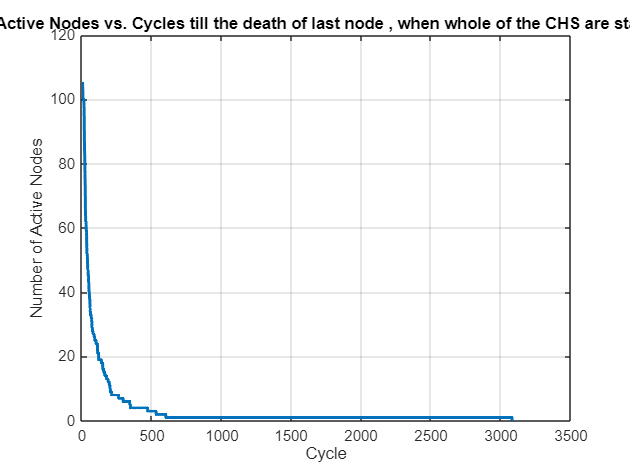

% Part E_B
% Plot Active Nodes vs. Cycles
figure(2);
plot(1:cycles, alive_nodes_per_cycle, 'LineWidth', 2);
title('Active Nodes vs. Cycles till the death of last node , when whole of the CHS are static');
xlabel('Cycle');
ylabel('Number of Active Nodes');
grid on;

**                                                               Fig [8]**

**            The Figure Shows Number of active Nodes VS number of Cycles till the death **

**                       of Last Node in the 100 Sensors Nodes , it appears it starts from 105 **

**                       which indicates the 100 sensor Nodes , with the 5 Special CHS ,**

**                                 and  it starts to decay till Whole of Nodes are dead . **

- **Part E_C_1** **Number of active Nodes VS Number of Cycles , till the death of  Last Node with Fixed CHS with Indication for T1_Sensor ,which indicates the First Sensor Node death from the 100 and T_Special , which  indicates the First Sepcial Nodes death from the 5 special Nodes : **

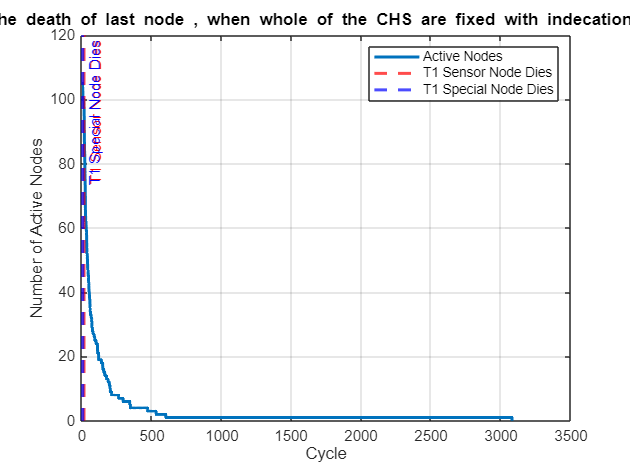

% Plot Active Nodes vs. Cycles
figure(3);
plot(1:cycles, alive_nodes_per_cycle, 'LineWidth', 2);
title('Active Nodes vs. Cycles  till the death of last node , when whole of the CHS are fixed with indecation for both T1_sensor and T1_Sepcial');
xlabel('Cycle');
ylabel('Number of Active Nodes');
grid on;
% Highlight T1 events
if ~isempty(T1_sensor)
    hold on;
    xline(T1_sensor, 'r--', 'LineWidth', 2, 'Label', 'T1 Sensor Node Dies');
end
if ~isempty(T1_special)
    xline(T1_special, 'b--', 'LineWidth', 2, 'Label', 'T1 Special Node Dies');
end
legend('Active Nodes', 'T1 Sensor Node Dies', 'T1 Special Node Dies');
hold off;

**                                                                      Fig [9]**

**            The Figure Shows Number of active Nodes VS number of Cycles till the death **

**                       of Last Node in the 100 Sensors Nodes with indication for T1_Sensor , **

**                        which indicates the First Node dead in the 100 sensor Nodes , **

**                            and T1_Special which indicates the First Node dead of **

**                                  the five special Nodes , it appears it starts from 105 **

**                                     which indicates the 100 sensor Nodes , **

**                                                    with the 5 Special CHS ,**

**                                                       and it starts to decay**

**                                                         till Whole of Nodes **

**                                                               are dead**

- **Part E_C_2**** The Whole Cycles taking through simulation, The Cycle at which First Sensor Node dead and First Special Node which is a Cluster head dead : **

% Part E_C_2
disp('Simulation Complete');

Simulation Complete


disp(['Total Cycles: ', num2str(cycles)]);

Total Cycles: 3081


if ~isempty(T1_sensor)
    disp(['Cycle of First Sensor Node Death (T1_sensor): ', num2str(T1_sensor)]);
end

Cycle of First Sensor Node Death (T1_sensor): 15


if ~isempty(T1_special)
    disp(['Cycle of First Special Node Death (T1_special): ', num2str(T1_special)]);
end

Cycle of First Special Node Death (T1_special): 6


- **Part E_C_3**** The  remaining Energy at the network , after T1_Sensor which indicates the first Sensor Nodes death , and T1_Special which indicates the First Special Node which is a Cluster head death : **

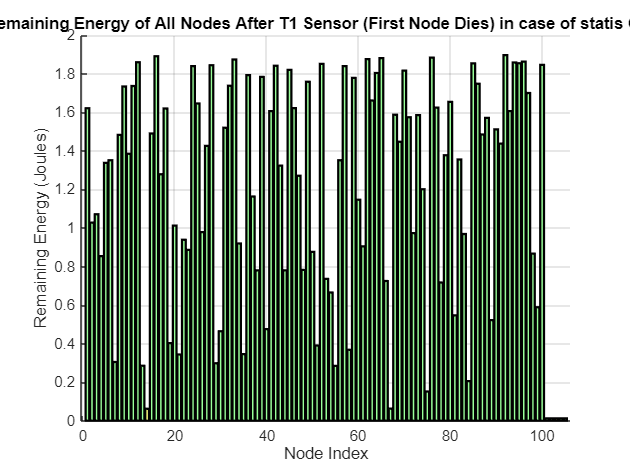

% Plot remaining energy after T1_Sensor for all nodes (sensor + special)
if ~isempty(T1_sensor)
    figure;
    % Set colors for alive (faded green) and dead (vibrant orange) nodes
    faded_alive_color =[0.6, 1, 0.6]; % Light pastel green for alive nodes
    bright_dead_color = [1, 1, 0.5];  % Vibrant orange for dead nodes
    hold on;
    % Plot remaining energy for general sensor nodes (1 to 100)
    for i = 1:100
        if ismember(i,dead_nodes_T1_S_N)
            bar(i, remaining_energy_per_cycle(T1_sensor, i), 'FaceColor', bright_dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
        else
            bar(i, remaining_energy_per_cycle(T1_sensor, i), 'FaceColor', faded_alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
        end
    end
    % Plot remaining energy for special nodes (101 to 105)
    for i = 101:105
        idx = i - 100;
        if ismember(idx,dead_nodes_T1_S)
            bar(i, remaining_energy_per_cycle(T1_sensor, i), 'FaceColor', bright_dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
        else
            bar(i, remaining_energy_per_cycle(T1_sensor, i), 'FaceColor', faded_alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
        end
    end
    title('Remaining Energy of All Nodes After T1 Sensor (First Node Dies) in case of statis CHS ');
    xlabel('Node Index');
    ylabel('Remaining Energy (Joules)');
    grid on;
    hold off;
end

                                                           **  Fig [10]**

**                    The Figure shows the remaining energy at the network after T1_Sensor ,**

**                               which indicates the death of first node of the 100 nodes , **

**                                 and its appears that whole alive nodes in green colour, **

**                                               and there's just one node in orange colour **

**                                                  which indicates the dead node and the **

**                                                         range of energies of them is**

**                                                                  among [0,2] , **

**                                                                    since whole **

**                                                                        special **

**                                                                        Nodes **

**                                                                        CHS are **

**                                                                           dead . **

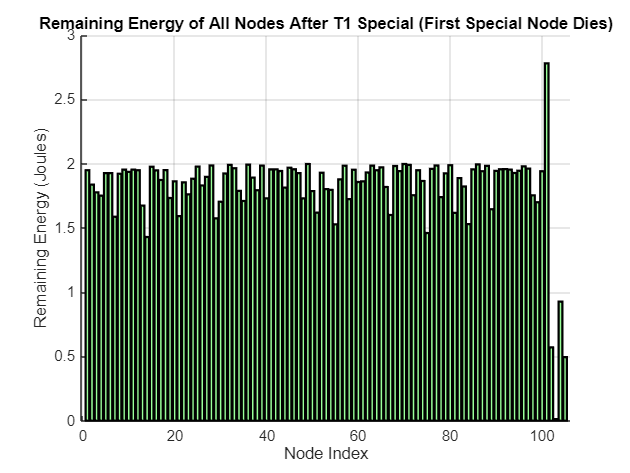

% Plot remaining energy after T1_Special for all nodes (sensor + special)
if ~isempty(T1_special)
    figure;
    % Set colors for alive (faded green) and dead (vibrant orange) nodes
    faded_alive_color =[0.6, 1, 0.6]; % Light pastel green for alive nodes
    bright_dead_color =[1, 1, 0.5];   % Vibrant orange for dead nodes
    dead_nodes_T1_S_N=[];
    hold on;
    % Plot remaining energy for general sensor nodes (1 to 100)
    for i = 1:100
        if ismember(i,dead_nodes_T1_S_N)
            bar(i, remaining_energy_per_cycle(T1_special, i), 'FaceColor', bright_dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
        else
            bar(i, remaining_energy_per_cycle(T1_special, i), 'FaceColor', faded_alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
        end
    end

    % Plot remaining energy for special nodes (101 to 105)
    for i = 101:105
        idx = i - 100;
        if ismember(idx,dead_nodes_T1_S)
            bar(i, remaining_energy_per_cycle(T1_special, i), 'FaceColor', bright_dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
        else
            bar(i, remaining_energy_per_cycle(T1_special, i), 'FaceColor', faded_alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
        end
    end
    
    title('Remaining Energy of All Nodes After T1 Special (First Special Node Dies)');
    xlabel('Node Index');
    ylabel('Remaining Energy (Joules)');
    grid on;
    hold off;
end

**                                                              Fig [11]**

**                    The Figure shows the remaining energy at the network after T1_Special,**

**                               which indicates the death of first node of the 5 nodes , **

**                                 and its appears that whole alive nodes in green colour, **

**                                               and there's just one node in orange colour **

**                                                  which indicates the dead node from **

**                                                      the special Nodes and the **

**                                                         range of energies of **

**                                                            them is among [0,2] , **

- **The Same simulation , before in part E to see the impact of varied R on the Network Life time and choose the Optimum one : **

clc; clear; close all;
% Parameters
N = 100;                                                    % Number of sensor nodes
A = 100;                                                    % Network area size (100m x 100m)
x = randi([0, A], 1, N);                                    % X-coordinates of sensor nodes
y = randi([0, A], 1, N);                                    % Y-coordinates of sensor nodes
E_initial = 2;                                              % Initial energy for sensor nodes (2 Joules)
E_special = 4;                                              % Initial energy for special nodes (4 Joules)
sink = [A/2, A/2];                                          % Sink located at the center
Eelec = 50e-9;                                              % Energy for transmitter/receiver circuitry (J/bit)
Eagg = 50e-9;                                               % Energy for aggregation (J/bit/signal)
epsilon_fs = 10e-9;                                         % Free-space energy parameter (J/bit/m^2)
epsilon_mp = 0.0013e-9;                                     % Multi-path energy parameter (J/bit/m^4)
d0 = sqrt(epsilon_fs / epsilon_mp);                         % Threshold distance
k = 4000;                                                   % Number of bits transmitted per cycle

% Varying R (Radius for special nodes)
R_values = 10:15:115;  % Range of R values (e.g., from 10m to 115 m)
cycles_per_R = zeros(1, length(R_values));  % Store the number of cycles for each R
T1_Sensor_R = zeros(1, length(R_values));  % Store the number of cycles for each R

for r_idx = 1:length(R_values)
    R = R_values(r_idx); % Set the radius for special nodes
    % Special nodes placement
    theta = linspace(0, 2*pi, 6);                               % Angles for special nodes
    theta(end) = [];                                            % Remove duplicate angle
    special_x = sink(1) + R * cos(theta);                       % X-coordinates of special nodes
    special_y = sink(2) + R * sin(theta);                       % Y-coordinates of special nodes
    % Initialize node states
    E = E_initial * ones(1, N);                                 % Energy for sensor nodes
    E_special_nodes = E_special * ones(1, 5);                   % Energy for special nodes
    node_dead = false(1, N);                                    % Sensor node death status
    special_node_dead = false(1, 5);                            % Special node death status
    alive_nodes = N;                                            % Number of alive sensor nodes
    alive_special_nodes = 5;                                    % Number of alive special nodes
    alive_nodes_per_cycle = [];                                 % Store number of active sensor nodes per cycle
    cycles = 0;                                                 % Cycle count
    T1_sensor = [];                                             % Cycle of first sensor node death
    T1_special = [];                                            % Cycle of first special node death
    % Simulation Loop for current R
    while alive_nodes > 0
        for i = find(~node_dead)
            % Distance to special nodes
            distances_to_special = sqrt((x(i) - special_x).^2 + (y(i) - special_y).^2);
            [min_dist, nearest_special_idx] = min(distances_to_special);
            % Check if all special nodes are dead
            if all(special_node_dead)
                min_dist = sqrt((x(i) - sink(1)).^2 + (y(i) - sink(2)).^2); % Direct to sink
            elseif special_node_dead(nearest_special_idx)
                distances_to_special(special_node_dead) = Inf; % Ignore dead special nodes
                [min_dist, nearest_special_idx] = min(distances_to_special);
            end
            % Energy consumption for transmission
            if min_dist <= d0
                energy_tx = k * Eelec + k * epsilon_fs * min_dist^2;
            else
                energy_tx = k * Eelec + k * epsilon_mp * min_dist^4;
            end
            
            % Update sensor node energy
            if E(i) > energy_tx
                E(i) = E(i) - energy_tx;
            else
                node_dead(i) = true;
                alive_nodes = alive_nodes - 1;
                if isempty(T1_sensor) && alive_nodes == N - 1
                    % Capture first dead nodes
                    T1_sensor = cycles + 1;
                end
                continue;
            end
            
            % Special node energy consumption
            if ~all(special_node_dead) && ~special_node_dead(nearest_special_idx)
                d_special_to_sink = sqrt((special_x(nearest_special_idx) - sink(1))^2 + (special_y(nearest_special_idx) - sink(2))^2);
                if d_special_to_sink <= d0
                    energy_special_tx = k * Eelec + k * epsilon_fs * d_special_to_sink^2 + k * Eagg;
                else
                    energy_special_tx = k * Eelec + k * epsilon_mp * d_special_to_sink^4 + k * Eagg;
                end
                if E_special_nodes(nearest_special_idx) > energy_special_tx
                    E_special_nodes(nearest_special_idx) = E_special_nodes(nearest_special_idx) - energy_special_tx;
                else
                    special_node_dead(nearest_special_idx) = true;
                    alive_special_nodes = alive_special_nodes - 1;
                    if isempty(T1_special) && alive_special_nodes == 4
                        T1_special = cycles + 1;
                    end
                end
            end
        end
        
        % Save total alive nodes
        total_alive_nodes = alive_nodes + alive_special_nodes;
        alive_nodes_per_cycle = [alive_nodes_per_cycle, total_alive_nodes];
        cycles = cycles + 1;
    end
    % Store the number of cycles for the current R value
    cycles_per_R(r_idx) = cycles;
    T1_Sensor_R(r_idx)=T1_sensor;
end
 

- **Part F_1**** A plot for Radious of CHS Versus Cycles per each Radious :** 

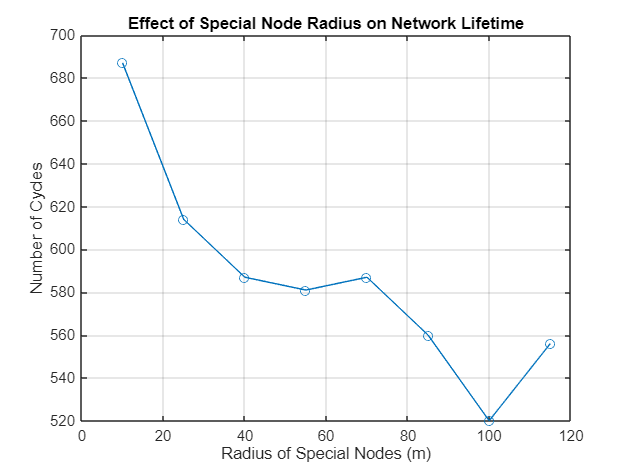

% Plot the results to find the optimal R
figure;
plot(R_values, cycles_per_R, '-o');
xlabel('Radius of Special Nodes (m)');
ylabel('Number of Cycles');
title('Effect of Special Node Radius on Network Lifetime');
grid on;

**                                                        Fig[12]**

**                     The Figure show the Number of Cycles VS radious of CHS **

**            which appears that Number of Cycles decrease with increasing Radious of CHS . **

- **Part F_2****  A plot for Radious of CHS Versus T1_Sensor at each R :  **

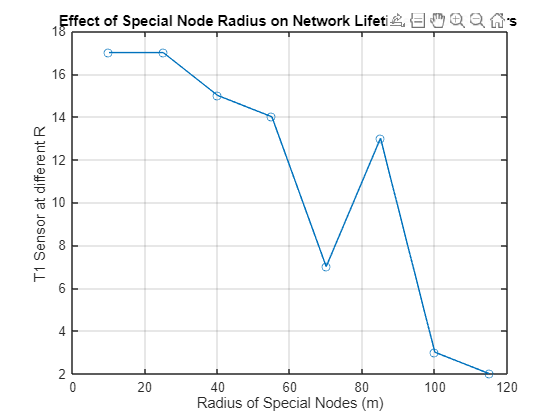

% Plot the results to find the optimal R
figure;
plot(R_values,T1_Sensor_R, '-o');
xlabel('Radius of Special Nodes (m)');
ylabel('T1 Sensor at different R ');
title('Effect of Special Node Radius on Network Lifetime T1 for Sensors ');
grid on;

**                                                                   Fig[13]**

**                         The Figure show the T1_Sensor which indicates the death of first node **

**                of the 100 sensor nodes VS radious of CHS which appears that T1_Sensor**

**                                     decrease with increasing Radious of CHS . **

- **Part F _3 ****The maximum radiou of CHS that maximuze the network Life time T1 for one for the 100 sensor Nodes : **

% Display the results and choose the best R value
[Max_T1_Sensors, best_R_idx] = max(T1_Sensor_R);
best_R = R_values(best_R_idx);
disp('Maximum T1 lifetime : :')

Maximum T1 lifetime : :


disp(Max_T1_Sensors);

    17



disp('Optimum radious that maximize T1:  ');

Optimum radious that maximize T1:  


disp(best_R);

    10



- **Part G :**** Based on the simulation, it appears that electing cluster heads (CHs) at every cycle maximizes the network lifetime T1� more effectively than using fixed CHs, which tends to minimize the network lifetime. It was observed that the impact of dynamic CH election is more favorable than the static configuration. The graphs below illustrate this comparison:**

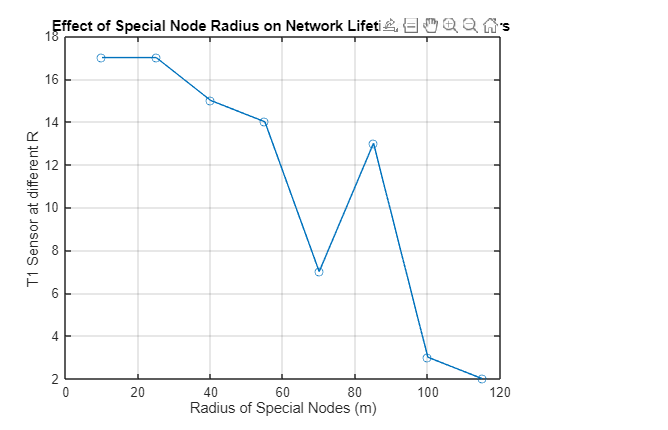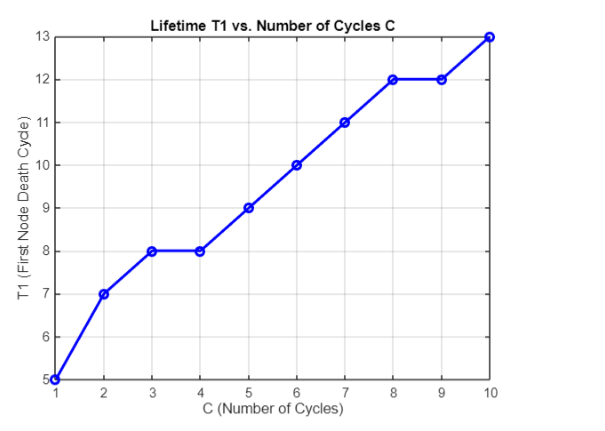

**                                                            Fig[14]                                                                                                                                    Fig[15]**

**            The Figure show the T1_Sensor which indicates the death of first node                                 The figure shows T1 which indicates the first node death VS Number of Cycles C ,**

**           of the 100 sensor nodes VS radious of CHS which appears that T1_Sensor                                         and it appears that T1 increases when C increase ,**

**                               decrease with increasing Radious of CHS .                                                                            which are the Cyles that  are used to elect the CHs .**

**-----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**-------------------------------------------------**

                                                                                                                                                                                                                                                                                                                                          **Done by. Nada tayel Khafagy  **

**                                                                                                                                                                                                                                                                                                   under the supervision of DR. Smay Soliman && Ta. Heba selim **

                                                                                                                                                                                                                                                                                                            **in Wireless Sensor network and IOT || CIE 510 || Fall 2024 **

**                                                                                                                                                                                                                                                                                                                                                 at UST || Zewail City**

**.**